[panel, fsp] = audioread("no_cancel_panel.wav");

[foam, fsf] = audioread("no_cancel_foam.wav");

[cancel_s, fs_s] = audioread("test_cancel_s.wav");
[cancel_h, fs_h] = audioread("test_cancel_h.wav");

t = (1:length(panel)) / fsp;
t = t';
size(t)

ans =       480256           1


size(panel)

ans =       480256           1


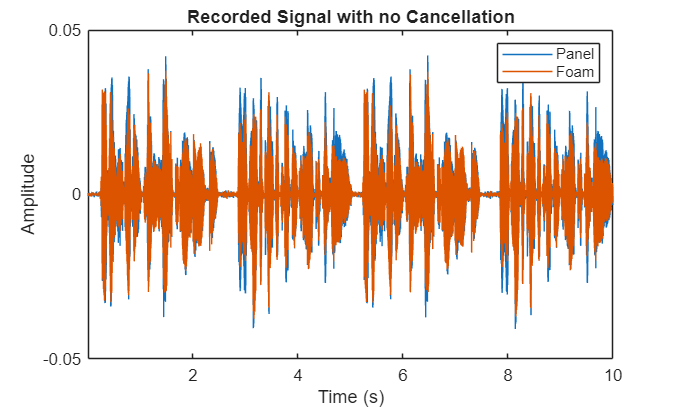

figure
plot(t, panel)
hold on
plot(t, foam) 
legend("Panel", "Foam")
xlim([t(1), t(end)])
title("Recorded Signal with no Cancellation")
xlabel("Time (s)")
ylabel("Amplitude")

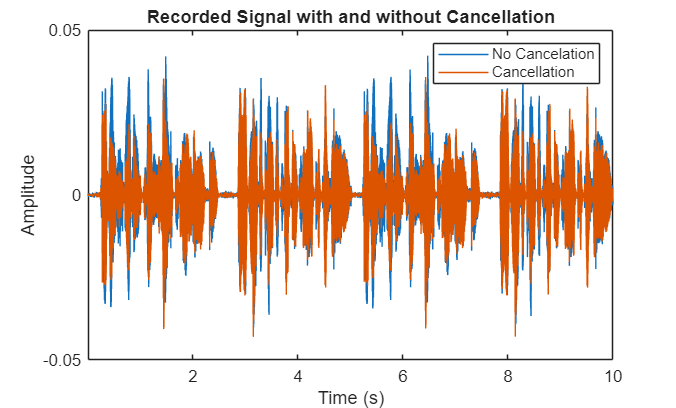

figure
plot(t, panel)
hold on
plot(t, cancel_s) 
legend("No Cancelation", "Cancellation")
xlim([t(1), t(end)])
title("Recorded Signal with and without Cancellation")
xlabel("Time (s)")
ylabel("Amplitude")

ms = @(x) mean(x.^2);
mse = @(x, y) mean((x - y).^2);

panel_ms = ms(panel)

panel_ms = 4.9884e-05

foam_ms = ms(foam)

foam_ms = 3.6789e-05

cancel_ms_s = ms(cancel_s);
cancel_ms_h = ms(cancel_h);


1 - (cancel_ms_s - foam_ms) / (panel_ms - foam_ms)

ans = 0.7668

1 - (cancel_ms_h - foam_ms) / (panel_ms - foam_ms)

ans = 0.1816